## Generate artificial data

clear all;

x = -4:0.05:4;
y = -4:0.05:4;

rng(123456);

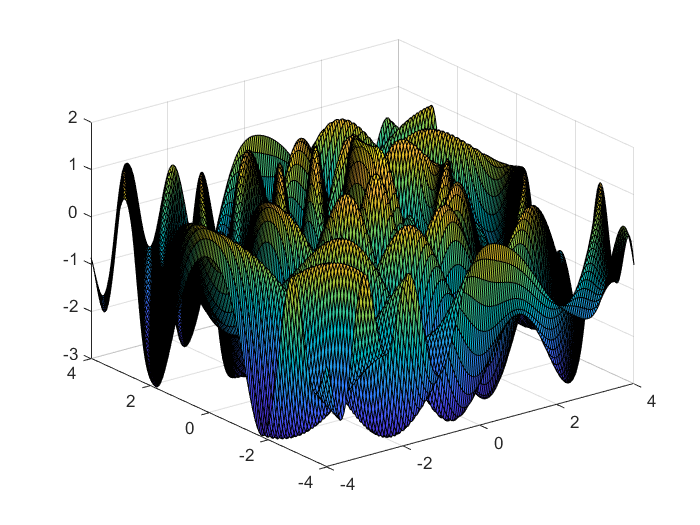

figure;
[X, Y] = meshgrid(x, y);
fkk = 4; % frequency of test function
freq=2*fkk; fk=1;
f1 = @(x,y) sin(freq*sqrt((x-fk).^2+y.^2));%./(freq*sqrt((x-fk).^2+y.^2));
freq=1*fkk; fk=-1;
f2 = @(x,y) -sin(freq*sqrt((x-fk).^2+y.^2));%./(freq*sqrt((x-fk).^2+y.^2));
freq = 0.1*fkk;
f3 = @(x,y) -sin(freq*sqrt(x.^2+y.^2));
ff = @(x,y) f1(x,y)+f2(x,y)+f3(x,y);
Z = ff(X, Y);
%Z = peaks(X, Y);
surf(X, Y, Z);

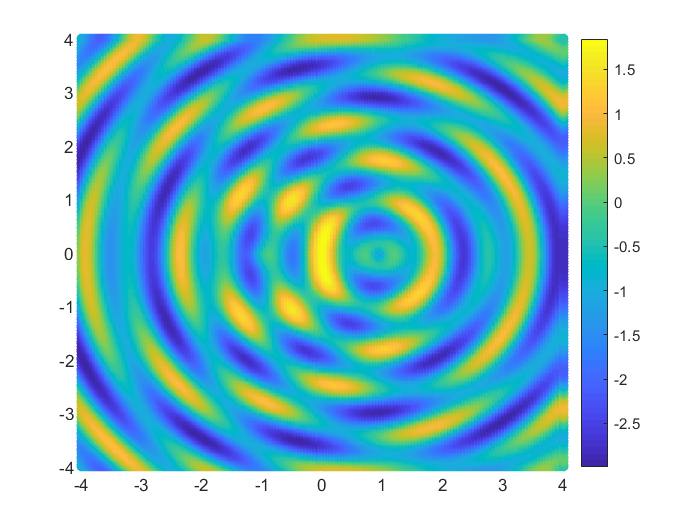

figure;
scatter(X(:), Y(:), [], Z(:), "filled");
colorbar;

xnorm = 1; ynorm = 1; % whether use normalization
yns = 0.1; % noise scale

n = 1e4; % size of training data
ttcs = 300;
ttm = round(n / (ttcs/2));

% represent_ratio = 5;
% dcs = 300; % size of the communication set
% mn = round(n / dcs); % mn is the number of experts (normal)
% m = round(n / (dcs*represent_ratio)); % m is the number of experts (sparse representative)
% lamds = 0:0.5:3.0;

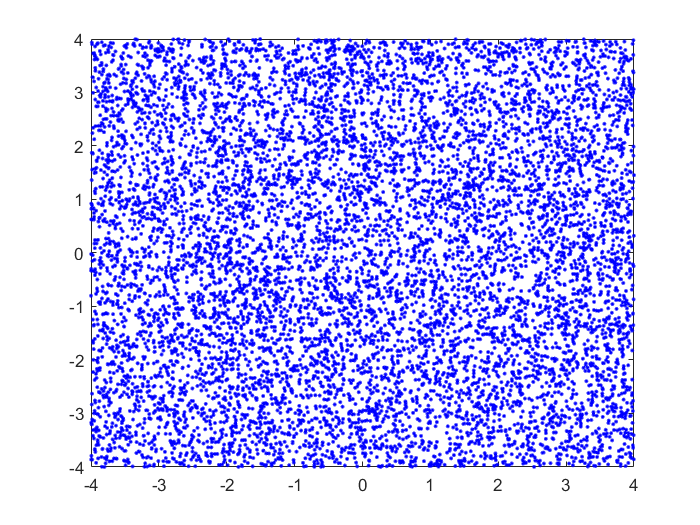

testsize = 2000; % size of test data
valsize = 1000;
induce_step = 100;

% training input
ori_all_trainxs = 8*(rand(n, 1)-0.5);
ori_all_trainys = 8*(rand(n, 1)-0.5);

figure;
plot(ori_all_trainxs, ori_all_trainys, 'b.');

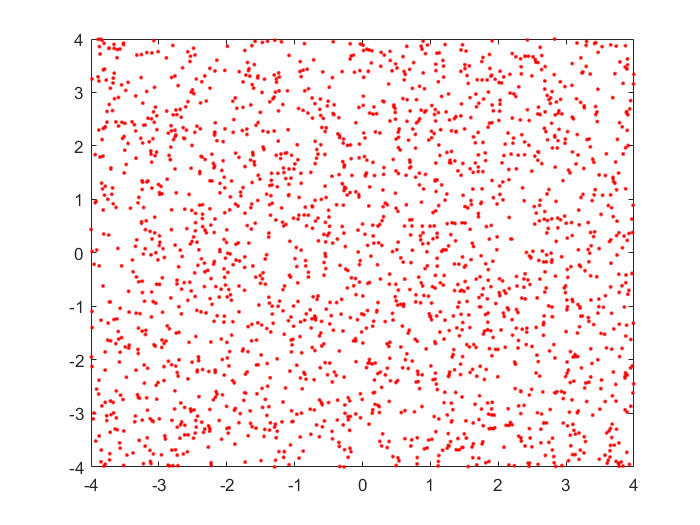


% test input
ori_testxs = 8*(rand(testsize, 1)-0.5);
ori_testys = 8*(rand(testsize, 1)-0.5);

% validation input
ori_valxs = 8*(rand(valsize, 1)-0.5);
ori_valys = 8*(rand(valsize, 1)-0.5);

figure;
plot(ori_testxs, ori_testys, 'r.');


% ininput normalization
if xnorm == 1
    norm_xmean = mean(ori_all_trainxs);
    norm_xstd = std(ori_all_trainxs);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    norm_ymean = mean(ori_all_trainys);
    norm_ystd = std(ori_all_trainys);
    all_trainys = (ori_all_trainys - norm_ymean) / norm_ystd;
    
    testxs = (ori_testxs - norm_xmean) / norm_xstd;
    testys = (ori_testys - norm_ymean) / norm_ystd;
    
    valxs = (ori_valxs - norm_xmean) / norm_xstd;
    valys = (ori_valys - norm_ymean) / norm_ystd;
else
    all_trainxs = ori_all_trainxs;
    all_trainys = ori_all_trainys;
    testxs = ori_testxs;
    testys = ori_testys;    
    valxs = ori_valxs;
    valys = ori_valys;    
end

% training output
ln = length(all_trainxs);
xvec = zeros(ln, 2); ori_xvec = zeros(ln, 2);
for i = 1:ln
    xvec(i, :) = [all_trainxs(i), all_trainys(i)];
    ori_xvec(i, :) = [ori_all_trainxs(i), ori_all_trainys(i)];
end
ori_yvec = ff(ori_all_trainxs, ori_all_trainys) + yns*randn(ln, 1);

% test output
ln = length(testxs);
xvec_test = zeros(ln, 2); ori_xvec_test = zeros(ln, 2);
for i = 1:ln
    xvec_test(i, :) = [testxs(i), testys(i)];
    ori_xvec_test(i, :) = [ori_testxs(i), ori_testys(i)];
end
ori_yvec_test = ff(ori_testxs, ori_testys) + yns*randn(ln, 1);

% validation output
ln = length(valxs);
xvec_val = zeros(ln, 2); ori_xvec_val = zeros(ln, 2);
for i = 1:ln
    xvec_val(i, :) = [valxs(i), valys(i)];
    ori_xvec_val(i, :) = [ori_valxs(i), ori_valys(i)];
end
ori_yvec_val = ff(ori_valxs, ori_valys) + yns*randn(ln, 1);

% output normalization
if ynorm == 1
    norm_fmean = mean(ori_yvec);
    norm_fstd = std(ori_yvec);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    yvec = (ori_yvec - norm_fmean) / norm_fstd;
    yvec_test = (ori_yvec_test - norm_fmean) / norm_fstd;
    yvec_val = (ori_yvec_val - norm_fmean) / norm_fstd;
else
    yvec = ori_yvec;
    yvec_test = ori_yvec_test;
    yvec_val = ori_yvec_val;
end

store results

kti = 5; % average over kti runs
grls = 0.3:0.05:1.0; % percentage of remaining data to be test
grbcm0_smse_rec = zeros(kti, 1);
rbcm0_smse_rec = zeros(kti, 1);
bcm0_smse_rec = zeros(kti, 1);
gpoe0_smse_rec = zeros(kti, 1);
poe0_smse_rec = zeros(kti, 1);
vfe0_smse_rec = zeros(kti, 1);
spgp0_smse_rec = zeros(kti, 1);
grbcm0_msll_rec = zeros(kti, 1);
rbcm0_msll_rec = zeros(kti, 1);
bcm0_msll_rec = zeros(kti, 1);
gpoe0_msll_rec = zeros(kti, 1);
poe0_msll_rec = zeros(kti, 1);
vfe0_msll_rec = zeros(kti, 1);
spgp0_msll_rec = zeros(kti, 1);
grbcm_gr_smse = zeros(kti, length(grls));
grbcm_gr_msll = zeros(kti, length(grls));
grbcm2_gr_smse = zeros(kti, length(grls));
grbcm2_gr_msll = zeros(kti, length(grls));
grbcm2_spgp_gr_smse = zeros(kti, length(grls));
grbcm2_spgp_gr_msll = zeros(kti, length(grls));

## Experiment I: remove data from the training set

sf2 = 1 ; ell = 1 ; sn2 = 0.1 ; 
d = size(xvec,2);
opts.Xnorm = 'N' ; opts.Ynorm = 'N' ;
opts.Ms = ttm+1;
opts.ell = ell ; opts.sf2 = sf2 ; opts.sn2 = sn2 ;
opts.meanfunc = []; opts.covfunc = @covSEard; opts.likfunc = @likGauss; opts.inffunc = @infGaussLik ;

meanfunc = [];                    % empty: don't use a mean function
covfunc = opts.covfunc;              % Squared Exponental covariance function
likfunc = opts.likfunc;              % Gaussian likelihood
inffunc = opts.inffunc;
km_iters = 1e4;
opts.induce_step = induce_step ;

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 50 ;
opts.Ms = ttm+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, []};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

% default partition
dcs_ecs_r = 0.5;
dcs = round(ttcs*dcs_ecs_r) % size of the communication set

dcs = 150

ecs = ttcs - dcs % size of other experts

ecs = 150

n_per = dcs ; % size of Dc
mn = round(n / ecs); % mn is the number of experts (normal)
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, mn,'MaxIter',km_iters);    

Baselines of VFE and SPGP.

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = mn+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 

Optimizing hyps in training...
Linesearch      0;  Value 2.393679e+04
Linesearch      1;  Value 1.176214e+04
Linesearch      2;  Value 6.163332e+03
Linesearch      3;  Value 5.854543e+03
Linesearch      4;  Value -1.986843e+03
Linesearch      5;  Value -2.496178e+03
Linesearch      6;  Value -3.208067e+03
Linesearch      7;  Value -3.350145e+03
Linesearch      8;  Value -4.258142e+03
Linesearch      9;  Value -4.488851e+03
Linesearch     10;  Value -4.528923e+03
Linesearch     11;  Value -4.531934e+03
Linesearch     12;  Value -4.534338e+03
Linesearch     13;  Value -4.535504e+03
Linesearch     14;  Value -4.535505e+03
Linesearch     15;  Value -4.535505e+03
Linesearch     16;  Value -4.535505e+03
Linesearch     17;  Value -4.535505e+03
Linesearch     18;  Value -4.535505e+03
Linesearch     19;  Value -4.535505e+03
Linesearch     20;  Value -4.535505e+03
Linesearch     21;  Value -4.535505e+03
Linesearch     22;  Value -4.535505e+03
Linesearch     23;  Value -4.535505e+03
Linesearch   

opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 150): MSE 0.01257547, SMSE 0.01196988, MSLL -1.96780742



g_opts.compute_hyp = 0;

When testing baseline, VFE and SPGP use all partition budget (ttcs = dcs + ecs).

I_com2 = Indics(1:ttcs) ; % randomly select communication set

% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com2, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
[vfe_hyp, tmp_nlzs] = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value 3.707323e+05
Function evaluation     16;  Value 3.304338e+05
Function evaluation     17;  Value 2.883060e+05
Function evaluation     20;  Value 2.542481e+05
Function evaluation     22;  Value 2.198459e+05
Function evaluation     24;  Value 2.087152e+05
Function evaluation     25;  Value 1.892107e+05
Function evaluation     27;  Value 1.756530e+05
Function evaluation     29;  Value 1.629768e+05
Function evaluation     31;  Value 1.563370e+05
Function evaluation     32;  Value 1.493191e+05
Function evaluation     34;  Value 1.443786e+05
Function evaluation     36;  Value 1.403163e+05
Function evaluation     38;  Value 1.373652e+05
Function evaluation     40;  Value 1.352177e+05
Function evaluation     42;  Value 1.325530e+05
Function evaluation     44;  Value 1.308722e+05
Function evaluation     45;  Value 1.291648e+05
Function evaluation     46;  Value 1.276831e+05
Function evaluation     48;  Value 1.264237e+05
Function evaluation     49;  Value 1.252

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE baseline', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE baseline (Dc size 150): MSE 0.05015171, SMSE 0.04773660, MSLL -1.24505517


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_size = ttcs;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com2, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,tmp_nlzs] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);

Function evaluation      0;  Value 8.003027e+03
Function evaluation     10;  Value 6.905067e+03
Function evaluation     11;  Value 5.751114e+03
Function evaluation     14;  Value 5.255732e+03
Function evaluation     15;  Value 4.824455e+03
Function evaluation     17;  Value 4.564236e+03
Function evaluation     18;  Value 4.297099e+03
Function evaluation     20;  Value 4.105163e+03
Function evaluation     21;  Value 3.896262e+03
Function evaluation     23;  Value 3.713547e+03
Function evaluation     24;  Value 3.527465e+03
Function evaluation     26;  Value 3.369774e+03
Function evaluation     28;  Value 3.258013e+03
Function evaluation     30;  Value 3.161050e+03
Function evaluation     32;  Value 3.092476e+03
Function evaluation     34;  Value 3.010800e+03
Function evaluation     36;  Value 2.959714e+03
Function evaluation     37;  Value 2.900693e+03
Function evaluation     39;  Value 2.872686e+03
Function evaluation     41;  Value 2.833612e+03
Function evaluation     42;  Value 2.792

xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;
[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE,spgpSMSE,spgpMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG baseline', n_per, spgpMSE,spgpSMSE,spgpMSLL);

SPSG baseline (Dc size 150): MSE 0.09106134, SMSE 0.08667618, MSLL -1.22127648


% spgp0_smse_rec(ki) = spgpSMSE; spgp0_msll_rec(ki) = spgpMSLL;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

Average over 5 runs.

==============1================

Optimizing hyps in training...
Linesearch      0;  Value 2.422999e+04
Linesearch      1;  Value 1.184364e+04
Linesearch      2;  Value 5.467047e+03
Linesearch      3;  Value 5.163614e+03
Linesearch      4;  Value -2.886670e+03
Linesearch      5;  Value -3.221907e+03
Linesearch      6;  Value -3.316389e+03
Linesearch      7;  Value -4.193879e+03
Linesearch      8;  Value -4.487277e+03
Linesearch      9;  Value -4.534952e+03
Linesearch     10;  Value -4.541689e+03
Linesearch     11;  Value -4.541862e+03
Linesearch     12;  Value -4.541866e+03
Linesearch     13;  Value -4.541867e+03
Linesearch     14;  Value -4.541867e+03
Linesearch     15;  Value -4.541867e+03
Linesearch     16;  Value -4.541867e+03
Linesearch     17;  Value -4.541867e+03
Linesearch     18;  Value -4.541867e+03
Linesearch     19;  Value -4.541867e+03
Linesearch     20;  Value -4.541867e+03
Linesearch     21;  Value -4.541867e+03
Linesearch     22;  Value -4.541867e+03
Linesearch     23;  Value -4.541867e+03
Linesearch   

GRBCM (Dc size 150): MSE 0.01244503, SMSE 0.01184573, MSLL -1.99268697


Function evaluation      0;  Value 7.167835e+05
Function evaluation     13;  Value 7.135049e+05
Function evaluation     18;  Value 6.435179e+05
Function evaluation     20;  Value 5.967653e+05
Function evaluation     22;  Value 5.630492e+05
Function evaluation     24;  Value 5.530678e+05
Function evaluation     25;  Value 5.374005e+05
Function evaluation     27;  Value 5.284854e+05
Function evaluation     29;  Value 5.202562e+05
Function evaluation     31;  Value 5.149289e+05
Function evaluation     33;  Value 5.125709e+05
Function evaluation     35;  Value 5.102987e+05
Function evaluation     37;  Value 5.082959e+05
Function evaluation     38;  Value 5.063377e+05
Function evaluation     40;  Value 5.046794e+05
Function evaluation     42;  Value 5.037219e+05
Function evaluation     44;  Value 5.013091e+05
Function evaluation     46;  Value 4.999898e+05
Function evaluation     48;  Value 4.994813e+05
Function evaluation     50;  Value 4.981589e+05
Function evaluation     52;  Value 4.963

VFE (Dc size 150): MSE 0.32919013, SMSE 0.31333761, MSLL -0.57504772


Function evaluation      0;  Value 1.214558e+04
Function evaluation      7;  Value 1.207189e+04
Function evaluation     13;  Value 1.103764e+04
Function evaluation     16;  Value 1.057551e+04
Function evaluation     17;  Value 1.027865e+04
Function evaluation     20;  Value 1.003783e+04
Function evaluation     21;  Value 9.796230e+03
Function evaluation     23;  Value 9.646574e+03
Function evaluation     24;  Value 9.500744e+03
Function evaluation     26;  Value 9.375495e+03
Function evaluation     28;  Value 9.288683e+03
Function evaluation     29;  Value 9.199393e+03
Function evaluation     31;  Value 9.130564e+03
Function evaluation     33;  Value 9.076951e+03
Function evaluation     34;  Value 9.018486e+03
Function evaluation     35;  Value 8.962642e+03
Function evaluation     37;  Value 8.922706e+03
Function evaluation     39;  Value 8.897277e+03
Function evaluation     41;  Value 8.868925e+03
Function evaluation     43;  Value 8.824209e+03
Function evaluation     45;  Value 8.799

SPSG (Dc size 150): MSE 0.42024017, SMSE 0.40000302, MSLL -0.57563766


GRBCM (VFE) (Dc size 150): MSE 0.01268806, SMSE 0.01207705, MSLL -1.98482061


GRBCM (SPGP) (Dc size 150): MSE 0.01247200, SMSE 0.01187140, MSLL -1.98605977


RBCM (Dc size 150): MSE 0.01281609, SMSE 0.0122, MSLL -1.8143


BCM (Dc size 150): MSE 0.01320222, SMSE 0.0126, MSLL -2.1741


PoE (Dc size 150): MSE 0.10237897, SMSE 0.0974, MSLL 3.7793


GPoE (Dc size 150): MSE 0.01268349, SMSE 0.0121, MSLL -1.8173


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

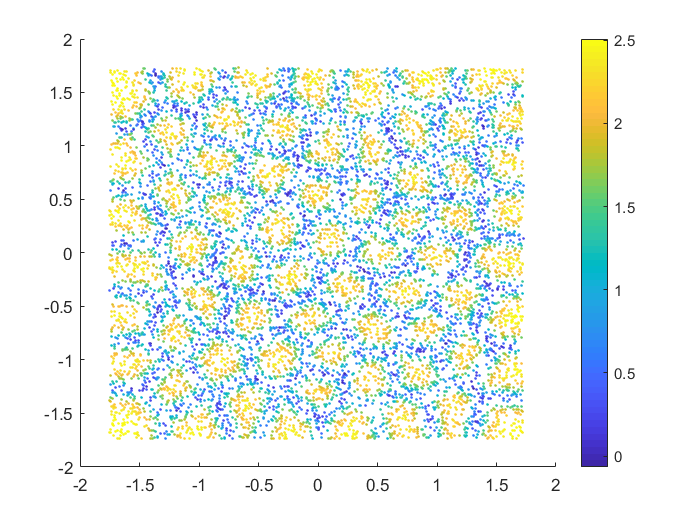

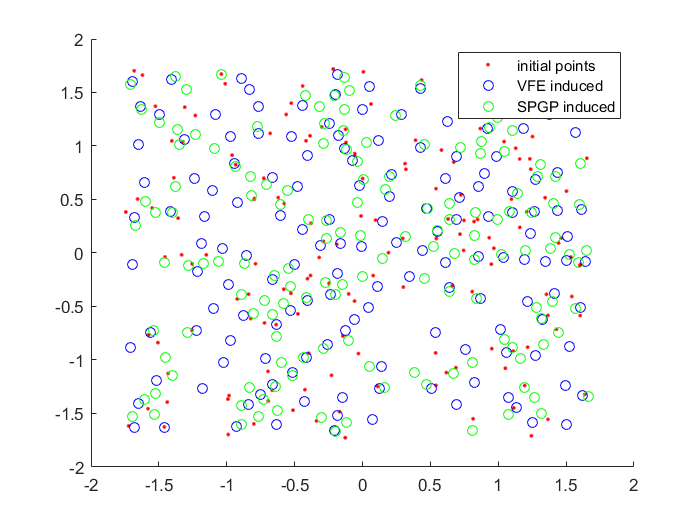

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.08618565, SMSE 0.0820, MSLL -1.4412


GRBCM++ (VFE) (Dc size 150): 
MSE 0.06124814, SMSE 0.0583, MSLL -1.5020


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.06089531, SMSE 0.0580, MSLL -1.5222


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.05622199, SMSE 0.0535, MSLL -1.5696


GRBCM++ (VFE) (Dc size 150): 
MSE 0.04410065, SMSE 0.0420, MSLL -1.6180


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.04424603, SMSE 0.0421, MSLL -1.6143


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.04352921, SMSE 0.0414, MSLL -1.6616


GRBCM++ (VFE) (Dc size 150): 
MSE 0.03543223, SMSE 0.0337, MSLL -1.6891


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.03619204, SMSE 0.0344, MSLL -1.6972


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.03348525, SMSE 0.0319, MSLL -1.7430


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02964483, SMSE 0.0282, MSLL -1.7639


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02935344, SMSE 0.0279, MSLL -1.7629


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.02715576, SMSE 0.0258, MSLL -1.8230


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02581090, SMSE 0.0246, MSLL -1.8305


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02450188, SMSE 0.0233, MSLL -1.8414


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.02326546, SMSE 0.0221, MSLL -1.8596


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02198821, SMSE 0.0209, MSLL -1.8761


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02152415, SMSE 0.0205, MSLL -1.8743


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01956203, SMSE 0.0186, MSLL -1.9070


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01950488, SMSE 0.0186, MSLL -1.9216


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01969445, SMSE 0.0187, MSLL -1.9034


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01721117, SMSE 0.0164, MSLL -1.9515


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01733029, SMSE 0.0165, MSLL -1.9694


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01721185, SMSE 0.0164, MSLL -1.9497


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01600575, SMSE 0.0152, MSLL -1.9756


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01589735, SMSE 0.0151, MSLL -1.9952


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01590606, SMSE 0.0151, MSLL -1.9706


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01540785, SMSE 0.0147, MSLL -1.9767


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01572814, SMSE 0.0150, MSLL -1.9853


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01555823, SMSE 0.0148, MSLL -1.9675


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01457902, SMSE 0.0139, MSLL -1.9773


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01454465, SMSE 0.0138, MSLL -1.9947


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01453589, SMSE 0.0138, MSLL -1.9723


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01368763, SMSE 0.0130, MSLL -1.9900


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01375648, SMSE 0.0131, MSLL -2.0046


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01374192, SMSE 0.0131, MSLL -1.9863


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01286398, SMSE 0.0122, MSLL -2.0089


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01300729, SMSE 0.0124, MSLL -2.0169


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01299667, SMSE 0.0124, MSLL -2.0010


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01264567, SMSE 0.0120, MSLL -1.9953


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01296308, SMSE 0.0123, MSLL -1.9877


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01282924, SMSE 0.0122, MSLL -1.9801


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01244503, SMSE 0.0118, MSLL -1.9927


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01268806, SMSE 0.0121, MSLL -1.9848


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01247200, SMSE 0.0119, MSLL -1.9861


==============2================

Optimizing hyps in training...
Linesearch      0;  Value 2.547383e+04
Linesearch      1;  Value 1.206295e+04
Linesearch      2;  Value 5.996622e+03
Linesearch      3;  Value 5.463941e+03
Linesearch      4;  Value -2.589468e+03
Linesearch      5;  Value -3.182883e+03
Linesearch      6;  Value -3.266081e+03
Linesearch      7;  Value -4.183049e+03
Linesearch      8;  Value -4.471594e+03
Linesearch      9;  Value -4.527934e+03
Linesearch     10;  Value -4.545090e+03
Linesearch     11;  Value -4.546736e+03
Linesearch     12;  Value -4.547707e+03
Linesearch     13;  Value -4.548013e+03
Linesearch     14;  Value -4.548060e+03
Linesearch     15;  Value -4.548060e+03
Linesearch     16;  Value -4.548061e+03
Linesearch     17;  Value -4.548061e+03
Linesearch     18;  Value -4.548061e+03
Linesearch     19;  Value -4.548061e+03
Linesearch     20;  Value -4.548061e+03
Linesearch     21;  Value -4.548061e+03
Linesearch     22;  Value -4.548061e+03
Linesearch     23;  Value -4.548061e+03
Linesearch   

GRBCM (Dc size 150): MSE 0.01267743, SMSE 0.01206694, MSLL -1.93005199


Function evaluation      0;  Value 7.357831e+05
Function evaluation     15;  Value 6.801936e+05
Function evaluation     17;  Value 6.398666e+05
Function evaluation     19;  Value 6.008916e+05
Function evaluation     21;  Value 5.896451e+05
Function evaluation     23;  Value 5.624808e+05
Function evaluation     25;  Value 5.495049e+05
Function evaluation     27;  Value 5.423183e+05
Function evaluation     29;  Value 5.362841e+05
Function evaluation     30;  Value 5.300302e+05
Function evaluation     32;  Value 5.249865e+05
Function evaluation     34;  Value 5.205486e+05
Function evaluation     36;  Value 5.182306e+05
Function evaluation     38;  Value 5.152773e+05
Function evaluation     40;  Value 5.133927e+05
Function evaluation     42;  Value 5.117631e+05
Function evaluation     44;  Value 5.105312e+05
Function evaluation     45;  Value 5.094888e+05
Function evaluation     46;  Value 5.083345e+05
Function evaluation     48;  Value 5.072469e+05
Function evaluation     50;  Value 5.064

VFE (Dc size 150): MSE 0.35244205, SMSE 0.33546980, MSLL -0.54369302


Function evaluation      0;  Value 1.159471e+04
Function evaluation      6;  Value 1.157571e+04
Function evaluation     11;  Value 1.094861e+04
Function evaluation     13;  Value 1.069584e+04
Function evaluation     14;  Value 1.041539e+04
Function evaluation     15;  Value 1.013506e+04
Function evaluation     17;  Value 9.931751e+03
Function evaluation     19;  Value 9.789063e+03
Function evaluation     20;  Value 9.643138e+03
Function evaluation     22;  Value 9.497941e+03
Function evaluation     24;  Value 9.413487e+03
Function evaluation     25;  Value 9.331380e+03
Function evaluation     27;  Value 9.269602e+03
Function evaluation     29;  Value 9.216081e+03
Function evaluation     31;  Value 9.174860e+03
Function evaluation     33;  Value 9.139270e+03
Function evaluation     34;  Value 9.104792e+03
Function evaluation     36;  Value 9.064375e+03
Function evaluation     37;  Value 9.024947e+03
Function evaluation     39;  Value 8.990141e+03
Function evaluation     41;  Value 8.961

SPSG (Dc size 150): MSE 0.45748500, SMSE 0.43545429, MSLL -0.54394736


GRBCM (VFE) (Dc size 150): MSE 0.01289921, SMSE 0.01227804, MSLL -1.95077649


GRBCM (SPGP) (Dc size 150): MSE 0.01297273, SMSE 0.01234802, MSLL -1.94537717


RBCM (Dc size 150): MSE 0.01304278, SMSE 0.0124, MSLL -1.7706


BCM (Dc size 150): MSE 0.01348841, SMSE 0.0128, MSLL -2.1561


PoE (Dc size 150): MSE 0.09763217, SMSE 0.0929, MSLL 3.4752


GPoE (Dc size 150): MSE 0.01288216, SMSE 0.0123, MSLL -1.7763


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.08096680, SMSE 0.0771, MSLL -1.5180


GRBCM++ (VFE) (Dc size 150): 
MSE 0.05164956, SMSE 0.0492, MSLL -1.5842


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.06048498, SMSE 0.0576, MSLL -1.5711


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.05529933, SMSE 0.0526, MSLL -1.6292


GRBCM++ (VFE) (Dc size 150): 
MSE 0.04066314, SMSE 0.0387, MSLL -1.6747


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.04345079, SMSE 0.0414, MSLL -1.6624


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.03834810, SMSE 0.0365, MSLL -1.7161


GRBCM++ (VFE) (Dc size 150): 
MSE 0.03253585, SMSE 0.0310, MSLL -1.7476


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.03454680, SMSE 0.0329, MSLL -1.7241


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.03182218, SMSE 0.0303, MSLL -1.7858


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02941045, SMSE 0.0280, MSLL -1.8077


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02881540, SMSE 0.0274, MSLL -1.7949


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.02640182, SMSE 0.0251, MSLL -1.8311


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02447352, SMSE 0.0233, MSLL -1.8666


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02597059, SMSE 0.0247, MSLL -1.8256


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.02325934, SMSE 0.0221, MSLL -1.8648


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02243629, SMSE 0.0214, MSLL -1.8903


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02347236, SMSE 0.0223, MSLL -1.8576


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01981496, SMSE 0.0189, MSLL -1.9182


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01947579, SMSE 0.0185, MSLL -1.9369


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02037404, SMSE 0.0194, MSLL -1.9072


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01727225, SMSE 0.0164, MSLL -1.9512


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01746546, SMSE 0.0166, MSLL -1.9700


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01736781, SMSE 0.0165, MSLL -1.9541


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01603982, SMSE 0.0153, MSLL -1.9679


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01659480, SMSE 0.0158, MSLL -1.9801


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01647180, SMSE 0.0157, MSLL -1.9657


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01514401, SMSE 0.0144, MSLL -1.9695


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01552512, SMSE 0.0148, MSLL -1.9826


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01548643, SMSE 0.0147, MSLL -1.9754


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01441326, SMSE 0.0137, MSLL -1.9492


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01486647, SMSE 0.0142, MSLL -1.9661


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01480535, SMSE 0.0141, MSLL -1.9511


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01348158, SMSE 0.0128, MSLL -1.9630


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01387903, SMSE 0.0132, MSLL -1.9829


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01388269, SMSE 0.0132, MSLL -1.9677


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01316646, SMSE 0.0125, MSLL -1.9460


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01351569, SMSE 0.0129, MSLL -1.9650


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01354017, SMSE 0.0129, MSLL -1.9562


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01283052, SMSE 0.0122, MSLL -1.9393


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01307901, SMSE 0.0124, MSLL -1.9637


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01325807, SMSE 0.0126, MSLL -1.9463


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01267743, SMSE 0.0121, MSLL -1.9301


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01289921, SMSE 0.0123, MSLL -1.9508


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01297273, SMSE 0.0123, MSLL -1.9454


==============3================

Optimizing hyps in training...
Linesearch      0;  Value 2.582557e+04
Linesearch      1;  Value 1.209224e+04
Linesearch      2;  Value 6.421659e+03
Linesearch      3;  Value 5.726784e+03
Linesearch      4;  Value -2.649959e+03
Linesearch      5;  Value -3.306634e+03
Linesearch      6;  Value -3.394757e+03
Linesearch      7;  Value -4.407108e+03
Linesearch      8;  Value -4.546302e+03
Linesearch      9;  Value -4.572753e+03
Linesearch     10;  Value -4.573757e+03
Linesearch     11;  Value -4.573838e+03
Linesearch     12;  Value -4.573848e+03
Linesearch     13;  Value -4.573849e+03
Linesearch     14;  Value -4.573850e+03
Linesearch     15;  Value -4.573850e+03
Linesearch     16;  Value -4.573850e+03
Linesearch     17;  Value -4.573850e+03
Linesearch     18;  Value -4.573850e+03
Linesearch     19;  Value -4.573850e+03
Linesearch     20;  Value -4.573850e+03
Linesearch     21;  Value -4.573850e+03


GRBCM (Dc size 150): MSE 0.01260542, SMSE 0.01199839, MSLL -1.95563677


Function evaluation      0;  Value 7.541337e+05
Function evaluation     12;  Value 7.494185e+05
Function evaluation     16;  Value 6.758437e+05
Function evaluation     20;  Value 6.397898e+05
Function evaluation     22;  Value 6.197247e+05
Function evaluation     23;  Value 5.891737e+05
Function evaluation     25;  Value 5.733100e+05
Function evaluation     27;  Value 5.644798e+05
Function evaluation     28;  Value 5.553467e+05
Function evaluation     30;  Value 5.504239e+05
Function evaluation     32;  Value 5.437676e+05
Function evaluation     33;  Value 5.372461e+05
Function evaluation     35;  Value 5.314527e+05
Function evaluation     37;  Value 5.286821e+05
Function evaluation     39;  Value 5.249675e+05
Function evaluation     41;  Value 5.199421e+05
Function evaluation     44;  Value 5.179744e+05
Function evaluation     45;  Value 5.158672e+05
Function evaluation     47;  Value 5.132880e+05
Function evaluation     49;  Value 5.117526e+05
Function evaluation     50;  Value 5.102

VFE (Dc size 150): MSE 0.34377903, SMSE 0.32722395, MSLL -0.56560340


Function evaluation      0;  Value 1.209042e+04
Function evaluation      8;  Value 1.201105e+04
Function evaluation     12;  Value 1.098944e+04
Function evaluation     15;  Value 1.056781e+04
Function evaluation     17;  Value 1.030808e+04
Function evaluation     19;  Value 1.012572e+04
Function evaluation     20;  Value 9.965014e+03
Function evaluation     21;  Value 9.788319e+03
Function evaluation     23;  Value 9.621219e+03
Function evaluation     25;  Value 9.500257e+03
Function evaluation     26;  Value 9.412316e+03
Function evaluation     28;  Value 9.335965e+03
Function evaluation     30;  Value 9.282144e+03
Function evaluation     32;  Value 9.215456e+03
Function evaluation     34;  Value 9.179156e+03
Function evaluation     36;  Value 9.125963e+03
Function evaluation     38;  Value 9.055797e+03
Function evaluation     40;  Value 9.017487e+03
Function evaluation     41;  Value 8.979078e+03
Function evaluation     42;  Value 8.941869e+03
Function evaluation     44;  Value 8.911

SPSG (Dc size 150): MSE 0.46082627, SMSE 0.43863466, MSLL -0.56903986


GRBCM (VFE) (Dc size 150): MSE 0.01257153, SMSE 0.01196613, MSLL -1.98402330


GRBCM (SPGP) (Dc size 150): MSE 0.01231244, SMSE 0.01171952, MSLL -1.98805066


RBCM (Dc size 150): MSE 0.01254621, SMSE 0.0119, MSLL -1.8346


BCM (Dc size 150): MSE 0.01314275, SMSE 0.0125, MSLL -2.1769


PoE (Dc size 150): MSE 0.10196945, SMSE 0.0971, MSLL 3.7554


GPoE (Dc size 150): MSE 0.01246089, SMSE 0.0119, MSLL -1.8357


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.08985974, SMSE 0.0855, MSLL -1.4800


GRBCM++ (VFE) (Dc size 150): 
MSE 0.04926116, SMSE 0.0469, MSLL -1.5744


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.05589050, SMSE 0.0532, MSLL -1.5869


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.06235844, SMSE 0.0594, MSLL -1.5740


GRBCM++ (VFE) (Dc size 150): 
MSE 0.04233645, SMSE 0.0403, MSLL -1.6429


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.04609913, SMSE 0.0439, MSLL -1.6544


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.04557645, SMSE 0.0434, MSLL -1.6642


GRBCM++ (VFE) (Dc size 150): 
MSE 0.03567895, SMSE 0.0340, MSLL -1.7192


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.03605901, SMSE 0.0343, MSLL -1.7309


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.03401892, SMSE 0.0324, MSLL -1.7423


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02900204, SMSE 0.0276, MSLL -1.7888


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02861337, SMSE 0.0272, MSLL -1.7982


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.02808145, SMSE 0.0267, MSLL -1.8143


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02426234, SMSE 0.0231, MSLL -1.8566


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02448703, SMSE 0.0233, MSLL -1.8586


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.02355599, SMSE 0.0224, MSLL -1.8763


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02266813, SMSE 0.0216, MSLL -1.8828


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02204703, SMSE 0.0210, MSLL -1.8959


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.02056007, SMSE 0.0196, MSLL -1.9134


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02026632, SMSE 0.0193, MSLL -1.9233


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01918001, SMSE 0.0183, MSLL -1.9403


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01814541, SMSE 0.0173, MSLL -1.9379


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01771062, SMSE 0.0169, MSLL -1.9600


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01724226, SMSE 0.0164, MSLL -1.9680


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01700347, SMSE 0.0162, MSLL -1.9408


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01698256, SMSE 0.0162, MSLL -1.9554


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01627094, SMSE 0.0155, MSLL -1.9748


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01542608, SMSE 0.0147, MSLL -1.9677


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01562202, SMSE 0.0149, MSLL -1.9768


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01493181, SMSE 0.0142, MSLL -1.9965


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01405632, SMSE 0.0134, MSLL -1.9770


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01458083, SMSE 0.0139, MSLL -1.9806


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01380011, SMSE 0.0131, MSLL -2.0075


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01360595, SMSE 0.0130, MSLL -1.9752


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01372576, SMSE 0.0131, MSLL -1.9965


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01326084, SMSE 0.0126, MSLL -2.0101


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01312055, SMSE 0.0125, MSLL -1.9728


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01342821, SMSE 0.0128, MSLL -1.9853


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01277363, SMSE 0.0122, MSLL -2.0111


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01277594, SMSE 0.0122, MSLL -1.9576


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01272917, SMSE 0.0121, MSLL -1.9920


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01250465, SMSE 0.0119, MSLL -1.9913


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01260542, SMSE 0.0120, MSLL -1.9556


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01257153, SMSE 0.0120, MSLL -1.9840


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01231244, SMSE 0.0117, MSLL -1.9881


==============4================

Optimizing hyps in training...
Linesearch      0;  Value 2.495245e+04
Linesearch      1;  Value 1.192853e+04
Linesearch      2;  Value 6.000879e+03
Linesearch      3;  Value 5.608080e+03
Linesearch      4;  Value -3.245131e+03
Linesearch      5;  Value -3.334369e+03
Linesearch      6;  Value -3.535008e+03
Linesearch      7;  Value -4.404544e+03
Linesearch      8;  Value -4.531659e+03
Linesearch      9;  Value -4.545213e+03
Linesearch     10;  Value -4.550063e+03
Linesearch     11;  Value -4.553632e+03
Linesearch     12;  Value -4.553737e+03
Linesearch     13;  Value -4.553741e+03
Linesearch     14;  Value -4.553741e+03
Linesearch     15;  Value -4.553741e+03
Linesearch     16;  Value -4.553741e+03
Linesearch     17;  Value -4.553741e+03
Linesearch     18;  Value -4.553741e+03
Linesearch     19;  Value -4.553741e+03
Linesearch     20;  Value -4.553741e+03
Linesearch     21;  Value -4.553741e+03
Linesearch     22;  Value -4.553741e+03
Linesearch     23;  Value -4.553741e+03
Linesearch   

GRBCM (Dc size 150): MSE 0.01257367, SMSE 0.01196817, MSLL -1.95072472


Function evaluation      0;  Value 7.273286e+05
Function evaluation     12;  Value 7.229906e+05
Function evaluation     17;  Value 6.764411e+05
Function evaluation     20;  Value 6.425866e+05
Function evaluation     22;  Value 6.148942e+05
Function evaluation     24;  Value 5.979267e+05
Function evaluation     26;  Value 5.844341e+05
Function evaluation     27;  Value 5.685099e+05
Function evaluation     29;  Value 5.576400e+05
Function evaluation     31;  Value 5.523321e+05
Function evaluation     33;  Value 5.485740e+05
Function evaluation     35;  Value 5.439960e+05
Function evaluation     37;  Value 5.412452e+05
Function evaluation     39;  Value 5.388291e+05
Function evaluation     41;  Value 5.378023e+05
Function evaluation     43;  Value 5.347418e+05
Function evaluation     45;  Value 5.336436e+05
Function evaluation     47;  Value 5.318177e+05
Function evaluation     49;  Value 5.309035e+05
Function evaluation     51;  Value 5.295981e+05
Function evaluation     53;  Value 5.286

VFE (Dc size 150): MSE 0.37368778, SMSE 0.35569242, MSLL -0.52557347


Function evaluation      0;  Value 1.161394e+04
Function evaluation      8;  Value 1.139851e+04
Function evaluation     10;  Value 1.128056e+04
Function evaluation     12;  Value 1.072488e+04
Function evaluation     15;  Value 1.039484e+04
Function evaluation     17;  Value 1.020227e+04
Function evaluation     19;  Value 1.000486e+04
Function evaluation     21;  Value 9.847490e+03
Function evaluation     24;  Value 9.775554e+03
Function evaluation     26;  Value 9.647100e+03
Function evaluation     28;  Value 9.540964e+03
Function evaluation     30;  Value 9.476288e+03
Function evaluation     32;  Value 9.404359e+03
Function evaluation     34;  Value 9.361512e+03
Function evaluation     36;  Value 9.318913e+03
Function evaluation     38;  Value 9.286628e+03
Function evaluation     40;  Value 9.265383e+03
Function evaluation     42;  Value 9.232850e+03
Function evaluation     44;  Value 9.213001e+03
Function evaluation     46;  Value 9.189394e+03
Function evaluation     47;  Value 9.165

SPSG (Dc size 150): MSE 0.44279123, SMSE 0.42146811, MSLL -0.56228035


GRBCM (VFE) (Dc size 150): MSE 0.01278409, SMSE 0.01216846, MSLL -1.95670773


GRBCM (SPGP) (Dc size 150): MSE 0.01240935, SMSE 0.01181177, MSLL -1.98198955


RBCM (Dc size 150): MSE 0.01268894, SMSE 0.0121, MSLL -1.8057


BCM (Dc size 150): MSE 0.01318720, SMSE 0.0126, MSLL -2.1704


PoE (Dc size 150): MSE 0.09685275, SMSE 0.0922, MSLL 3.3851


GPoE (Dc size 150): MSE 0.01261829, SMSE 0.0120, MSLL -1.8029


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.07373933, SMSE 0.0702, MSLL -1.5141


GRBCM++ (VFE) (Dc size 150): 
MSE 0.05390936, SMSE 0.0513, MSLL -1.5772


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.05560037, SMSE 0.0529, MSLL -1.5794


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.06144136, SMSE 0.0585, MSLL -1.5868


GRBCM++ (VFE) (Dc size 150): 
MSE 0.04650714, SMSE 0.0443, MSLL -1.6459


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.04651279, SMSE 0.0443, MSLL -1.6555


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.04587743, SMSE 0.0437, MSLL -1.6749


GRBCM++ (VFE) (Dc size 150): 
MSE 0.03676567, SMSE 0.0350, MSLL -1.7217


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.03723318, SMSE 0.0354, MSLL -1.7236


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.03501903, SMSE 0.0333, MSLL -1.7589


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02974144, SMSE 0.0283, MSLL -1.8085


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02948178, SMSE 0.0281, MSLL -1.8056


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.02938119, SMSE 0.0280, MSLL -1.8033


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02683626, SMSE 0.0255, MSLL -1.8503


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02585180, SMSE 0.0246, MSLL -1.8593


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.02440563, SMSE 0.0232, MSLL -1.8731


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02269089, SMSE 0.0216, MSLL -1.9023


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02269183, SMSE 0.0216, MSLL -1.8987


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.02049987, SMSE 0.0195, MSLL -1.9163


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01962400, SMSE 0.0187, MSLL -1.9416


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01954882, SMSE 0.0186, MSLL -1.9407


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01829367, SMSE 0.0174, MSLL -1.9428


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01794791, SMSE 0.0171, MSLL -1.9615


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01790830, SMSE 0.0170, MSLL -1.9627


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01664741, SMSE 0.0158, MSLL -1.9591


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01654960, SMSE 0.0158, MSLL -1.9732


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01620193, SMSE 0.0154, MSLL -1.9799


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01547138, SMSE 0.0147, MSLL -1.9730


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01566137, SMSE 0.0149, MSLL -1.9803


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01548781, SMSE 0.0147, MSLL -1.9833


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01424892, SMSE 0.0136, MSLL -1.9911


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01427557, SMSE 0.0136, MSLL -2.0045


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01406679, SMSE 0.0134, MSLL -2.0063


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01352382, SMSE 0.0129, MSLL -1.9934


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01352553, SMSE 0.0129, MSLL -2.0136


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01331280, SMSE 0.0127, MSLL -2.0127


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01292721, SMSE 0.0123, MSLL -1.9883


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01304856, SMSE 0.0124, MSLL -2.0038


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01273720, SMSE 0.0121, MSLL -2.0116


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01266939, SMSE 0.0121, MSLL -1.9692


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01291541, SMSE 0.0123, MSLL -1.9763


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01257218, SMSE 0.0120, MSLL -1.9895


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01257367, SMSE 0.0120, MSLL -1.9507


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01278409, SMSE 0.0122, MSLL -1.9567


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01240935, SMSE 0.0118, MSLL -1.9820


==============5================

Optimizing hyps in training...
Linesearch      0;  Value 2.435948e+04
Linesearch      1;  Value 1.184032e+04
Linesearch      2;  Value 5.975864e+03
Linesearch      3;  Value 5.618184e+03
Linesearch      4;  Value -2.346979e+03
Linesearch      5;  Value -3.169518e+03
Linesearch      6;  Value -3.305710e+03
Linesearch      7;  Value -3.426029e+03
Linesearch      8;  Value -3.844988e+03
Linesearch      9;  Value -4.349581e+03
Linesearch     10;  Value -4.552160e+03
Linesearch     11;  Value -4.563185e+03
Linesearch     12;  Value -4.564395e+03
Linesearch     13;  Value -4.566200e+03
Linesearch     14;  Value -4.566593e+03
Linesearch     15;  Value -4.566595e+03
Linesearch     16;  Value -4.566595e+03
Linesearch     17;  Value -4.566595e+03
Linesearch     18;  Value -4.566595e+03
Linesearch     19;  Value -4.566595e+03
Linesearch     20;  Value -4.566595e+03
Linesearch     21;  Value -4.566595e+03
Linesearch     22;  Value -4.566595e+03


GRBCM (Dc size 150): MSE 0.01240993, SMSE 0.01181231, MSLL -1.96659440


Function evaluation      0;  Value 7.413348e+05
Function evaluation     13;  Value 7.003969e+05
Function evaluation     14;  Value 6.393704e+05
Function evaluation     16;  Value 6.063719e+05
Function evaluation     18;  Value 5.820468e+05
Function evaluation     20;  Value 5.665873e+05
Function evaluation     22;  Value 5.548630e+05
Function evaluation     24;  Value 5.477949e+05
Function evaluation     26;  Value 5.423127e+05
Function evaluation     28;  Value 5.377375e+05
Function evaluation     30;  Value 5.349731e+05
Function evaluation     32;  Value 5.321149e+05
Function evaluation     34;  Value 5.305747e+05
Function evaluation     36;  Value 5.285404e+05
Function evaluation     37;  Value 5.264078e+05
Function evaluation     39;  Value 5.249596e+05
Function evaluation     41;  Value 5.223597e+05
Function evaluation     43;  Value 5.215322e+05
Function evaluation     45;  Value 5.206437e+05
Function evaluation     47;  Value 5.193371e+05
Function evaluation     49;  Value 5.182

VFE (Dc size 150): MSE 0.35400207, SMSE 0.33695470, MSLL -0.54679777


Function evaluation      0;  Value 1.184067e+04
Function evaluation      9;  Value 1.141055e+04
Function evaluation     10;  Value 1.098025e+04
Function evaluation     11;  Value 1.077812e+04
Function evaluation     13;  Value 1.033302e+04
Function evaluation     15;  Value 1.012674e+04
Function evaluation     17;  Value 9.947207e+03
Function evaluation     19;  Value 9.763196e+03
Function evaluation     20;  Value 9.593534e+03
Function evaluation     22;  Value 9.467632e+03
Function evaluation     24;  Value 9.355456e+03
Function evaluation     26;  Value 9.303363e+03
Function evaluation     28;  Value 9.239611e+03
Function evaluation     29;  Value 9.198911e+03
Function evaluation     31;  Value 9.115554e+03
Function evaluation     33;  Value 9.055232e+03
Function evaluation     34;  Value 8.998185e+03
Function evaluation     36;  Value 8.965161e+03
Function evaluation     38;  Value 8.935549e+03
Function evaluation     39;  Value 8.904013e+03
Function evaluation     41;  Value 8.869

SPSG (Dc size 150): MSE 0.44057428, SMSE 0.41935792, MSLL -0.56608380


GRBCM (VFE) (Dc size 150): MSE 0.01267798, SMSE 0.01206746, MSLL -1.96755443


GRBCM (SPGP) (Dc size 150): MSE 0.01243119, SMSE 0.01183256, MSLL -1.96220512


RBCM (Dc size 150): MSE 0.01276805, SMSE 0.0122, MSLL -1.8032


BCM (Dc size 150): MSE 0.01332427, SMSE 0.0127, MSLL -2.1660


PoE (Dc size 150): MSE 0.09983053, SMSE 0.0950, MSLL 3.6090


GPoE (Dc size 150): MSE 0.01268752, SMSE 0.0121, MSLL -1.8034


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.08438643, SMSE 0.0803, MSLL -1.4802


GRBCM++ (VFE) (Dc size 150): 
MSE 0.05430907, SMSE 0.0517, MSLL -1.5503


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.05778295, SMSE 0.0550, MSLL -1.5659


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.05639249, SMSE 0.0537, MSLL -1.6176


GRBCM++ (VFE) (Dc size 150): 
MSE 0.04073539, SMSE 0.0388, MSLL -1.6645


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.04276373, SMSE 0.0407, MSLL -1.6792


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.03973317, SMSE 0.0378, MSLL -1.7186


GRBCM++ (VFE) (Dc size 150): 
MSE 0.03279330, SMSE 0.0312, MSLL -1.7434


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.03312330, SMSE 0.0315, MSLL -1.7530


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.03171281, SMSE 0.0302, MSLL -1.7991


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02924390, SMSE 0.0278, MSLL -1.8135


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02843066, SMSE 0.0271, MSLL -1.8291


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.02636145, SMSE 0.0251, MSLL -1.8583


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02496073, SMSE 0.0238, MSLL -1.8731


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02397708, SMSE 0.0228, MSLL -1.8876


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.02291914, SMSE 0.0218, MSLL -1.8983


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02117163, SMSE 0.0202, MSLL -1.9231


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02086516, SMSE 0.0199, MSLL -1.9320


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01906484, SMSE 0.0181, MSLL -1.9412


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01843045, SMSE 0.0175, MSLL -1.9565


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01831077, SMSE 0.0174, MSLL -1.9600


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01712515, SMSE 0.0163, MSLL -1.9636


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01734981, SMSE 0.0165, MSLL -1.9669


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01654562, SMSE 0.0157, MSLL -1.9774


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01556757, SMSE 0.0148, MSLL -1.9896


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01594446, SMSE 0.0152, MSLL -1.9848


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01528047, SMSE 0.0145, MSLL -1.9904


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01481407, SMSE 0.0141, MSLL -1.9927


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01499191, SMSE 0.0143, MSLL -1.9976


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01478674, SMSE 0.0141, MSLL -1.9893


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01376916, SMSE 0.0131, MSLL -2.0158


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01390779, SMSE 0.0132, MSLL -2.0179


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01387972, SMSE 0.0132, MSLL -2.0094


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01291976, SMSE 0.0123, MSLL -2.0246


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01322800, SMSE 0.0126, MSLL -2.0256


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01302738, SMSE 0.0124, MSLL -2.0154


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01261762, SMSE 0.0120, MSLL -2.0122


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01279980, SMSE 0.0122, MSLL -2.0167


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01264687, SMSE 0.0120, MSLL -2.0068


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01238591, SMSE 0.0118, MSLL -1.9952


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01275656, SMSE 0.0121, MSLL -1.9850


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01246825, SMSE 0.0119, MSLL -1.9856


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01240993, SMSE 0.0118, MSLL -1.9666


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01267798, SMSE 0.0121, MSLL -1.9676


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01243119, SMSE 0.0118, MSLL -1.9622


kti = 5;
m = mn;

for ki=1:kti
fprintf("==============%d================", ki)
n_per = dcs ; % size of Dc
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, m,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = m+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 
opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE_bl,grbcmSMSE_bl,grbcmMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE_bl,grbcmSMSE_bl,grbcmMSLL_bl);
grbcm0_smse_rec(ki) = grbcmSMSE_bl; grbcm0_msll_rec(ki) = grbcmMSLL_bl;
g_opts.compute_hyp = 0;


% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
vfe_hyp = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);
vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE_bl,vfeSMSE_bl,vfeMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE', n_per, vfeMSE_bl,vfeSMSE_bl,vfeMSLL_bl);
vfe0_smse_rec(ki) = vfeSMSE_bl; vfe0_msll_rec(ki) = vfeMSLL_bl;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,f] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);
xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;

[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE_bl,spgpSMSE_bl,spgpMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG', n_per, spgpMSE_bl,spgpSMSE_bl,spgpMSLL_bl);
spgp0_smse_rec(ki) = spgpSMSE_bl; spgp0_msll_rec(ki) = spgpMSLL_bl;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

vfe_opts.grbcm_baseline = 0;
vfe_opts.global_index = ones(n,1);
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM (VFE)', n_per, MSE,SMSE,MSLL);

sp_opts.grbcm_baseline = 0;
sp_opts.global_index = ones(n,1);
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM (SPGP)', n_per, MSE,SMSE,MSLL);


criterion = 'RBCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[rbcmMSE,rbcmSMSE,rbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, rbcmMSE,rbcmSMSE,rbcmMSLL);
rbcm0_smse_rec(ki) = rbcmSMSE; rbcm0_msll_rec(ki) = rbcmMSLL;

criterion = 'BCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[bcmMSE,bcmSMSE,bcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, bcmMSE,bcmSMSE,bcmMSLL);
bcm0_smse_rec(ki) = bcmSMSE; bcm0_msll_rec(ki) = bcmMSLL;

criterion = 'PoE';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[poeMSE,poeSMSE,poeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, poeMSE,poeSMSE,poeMSLL);
poe0_smse_rec(ki) = poeSMSE; poe0_msll_rec(ki) = poeMSLL;

criterion = 'GPoE';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[gpoeMSE,gpoeSMSE,gpoeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, gpoeMSE,gpoeSMSE,gpoeMSLL);
gpoe0_smse_rec(ki) = gpoeSMSE; gpoe0_msll_rec(ki) = gpoeMSLL;

% compute informatic importance
ds = zeros(n, m);
for i=1:n
    for j=1:m
        %ds(i,j) = muti1(i)-muti2(j,i)+muti1(j)-muti2(i,j);
        ds(i,j) = norm(xvec(i, :) - C(j,:));
    end
end
% 1st closest cluster centers
[~, fcc] = min(ds, [], 2);
% set to inf
for i=1:n
    ds(i, fcc(i)) = 1e10;
end
% 2st closest cluster centers
[~, scc] = min(ds, [], 2);
rk = zeros(n, 1);
for iik=1:n
    if mod(iik, 1e2)==0
        fprintf('processing distance: %d/%d\n', iik, n);
    end
    i = fcc(iik);
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,models{i+1}.X,models{i+1}.Y,xvec(iik,:));
    h1 = 0.5*log(tmp_sig2);
    j = scc(iik);
%     [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
%         covfunc,likfunc,[models{i+1}.X;models{j+1}.X],[models{i+1}.Y;models{j+1}.Y],xvec(iik,:));
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,[models{j+1}.X],[models{j+1}.Y],xvec(iik,:));
    h2 = 0.5*log(tmp_sig2);
    rk(iik) = h2 - h1; % importance is the difference between mutual information
end

if ki==1
    figure;
    scatter(xvec(:,1), xvec(:,2), 3, rk, "filled"); colorbar;
    figure; hold on;
    plot(xvec(I_com,1), xvec(I_com,2), 'r.');
    plot(vfe_opts.xu(:,1), vfe_opts.xu(:,2), 'bo');
    plot(sp_opts.xu(:,1), sp_opts.xu(:,2), 'go');
    legend('initial points', 'VFE induced', 'SPGP induced'); 
end

for kj=1:length(grls) % test/validate different remaining percentage
    kj
    gr=grls(kj)
    crk = rk;
    crk(I_com) = -1e10;
    [~, crk_idx] = sort(crk, 'descend');
    rn = round(n*gr);
    global_index = zeros(n,1);
    global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance
    
    % only remove data from subsets, in RBGCM
    g_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,g_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);
    grbcm_gr_smse(ki,kj) = grbcmSMSE; grbcm_gr_msll(ki,kj) = grbcmMSLL;

    vfe_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);
    grbcm2_gr_smse(ki,kj) = SMSE; grbcm2_gr_msll(ki,kj) = MSLL;
    
    sp_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (SPGP)', n_per, MSE,SMSE,MSLL);
    grbcm2_spgp_gr_smse(ki,kj) = SMSE; grbcm2_spgp_gr_msll(ki,kj) = MSLL;
end   
end

Display results

grbcm0_smse = mean(grbcm0_smse_rec(1:kti)); grbcm0_msll = mean(grbcm0_msll_rec(1:kti));
rbcm0_smse = mean(rbcm0_smse_rec(1:kti)); rbcm0_msll = mean(rbcm0_msll_rec(1:kti));
bcm0_smse = mean(bcm0_smse_rec(1:kti)); bcm0_msll = mean(bcm0_msll_rec(1:kti));
poe0_smse = mean(poe0_smse_rec(1:kti)); poe0_msll = mean(poe0_msll_rec(1:kti));
gpoe0_smse = mean(gpoe0_smse_rec(1:kti)); gpoe0_msll = mean(gpoe0_msll_rec(1:kti));
vfe0_smse = mean(vfe0_smse_rec(1:kti)); vfe0_msll = mean(vfe0_msll_rec(1:kti));
spgp0_smse = mean(spgp0_smse_rec(1:kti)); spgp0_msll = mean(spgp0_msll_rec(1:kti));

fprintf('GRBCM: %6.8f, %6.4f', grbcm0_smse, grbcm0_msll);

GRBCM: 0.01193831, -1.9591

fprintf('RBCM: %6.8f, %6.4f', rbcm0_smse, rbcm0_msll);

RBCM: 0.01215734, -1.8057

fprintf('BCM: %6.8f, %6.4f', bcm0_smse, bcm0_msll);

BCM: 0.01262999, -2.1687

fprintf('GPoE: %6.8f, %6.4f', gpoe0_smse, gpoe0_msll);

GPoE: 0.01205650, -1.8071

fprintf('PoE: %6.8f, %6.4f', poe0_smse, poe0_msll);

PoE: 0.09493003, 3.6008

fprintf('VFE: %6.8f, %6.4f', vfe0_smse, vfe0_msll);

VFE: 0.33373569, -0.5513

fprintf('SPGP: %6.8f, %6.4f', spgp0_smse, spgp0_msll);

SPGP: 0.42298360, -0.5634

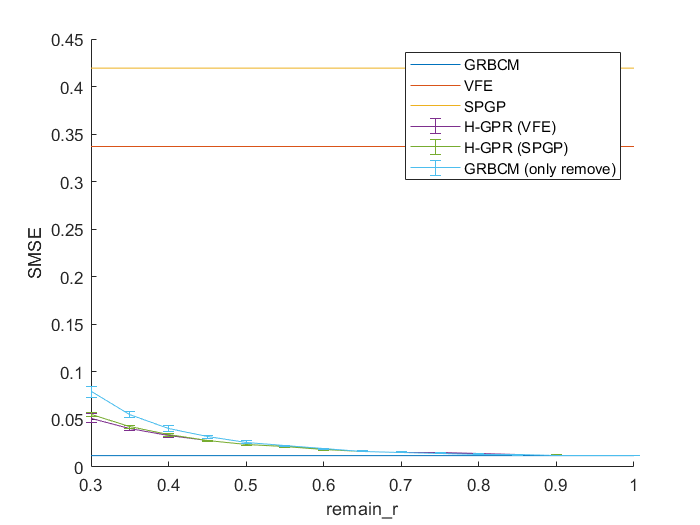

aamse = grbcm2_gr_smse(1:kti,:);
aamsll = grbcm2_gr_msll(1:kti,:);
mmse = mean(aamse);
mstd = std(aamse);
mmse_ro = mean(grbcm_gr_smse(1:kti,:));
mstd_ro = std(grbcm_gr_smse(1:kti,:));
mmse_sp = mean(grbcm2_spgp_gr_smse(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_smse(1:kti,:));

figure; hold on;
plot([min(grls), max(grls)], [grbcm0_smse,grbcm0_smse]);
plot([min(grls), max(grls)], [vfeSMSE_bl,vfeSMSE_bl]);
plot([min(grls), max(grls)], [spgpSMSE_bl,spgpSMSE_bl]);
errorbar(grls, mmse, mstd);
errorbar(grls, mmse_sp, mstd_sp);
errorbar(grls, mmse_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('SMSE');

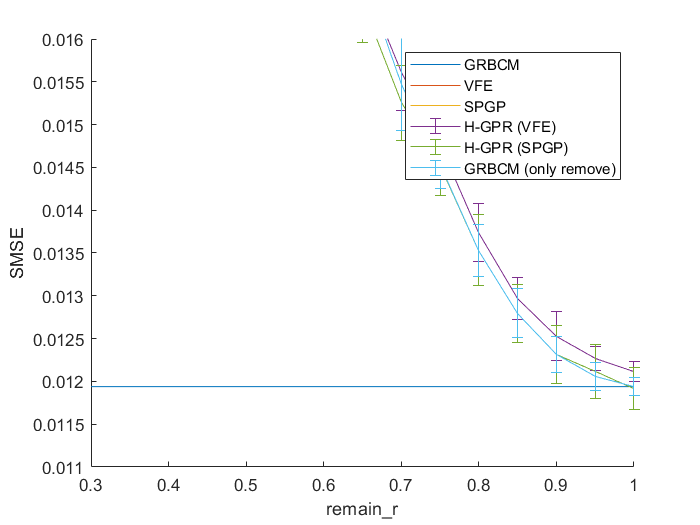

aamse = grbcm2_gr_smse(1:kti,:);
aamsll = grbcm2_gr_msll(1:kti,:);
mmse = mean(aamse);
mstd = std(aamse);
mmse_ro = mean(grbcm_gr_smse(1:kti,:));
mstd_ro = std(grbcm_gr_smse(1:kti,:));
mmse_sp = mean(grbcm2_spgp_gr_smse(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_smse(1:kti,:));

figure; hold on;
plot([min(grls), max(grls)], [grbcm0_smse,grbcm0_smse]);
plot([min(grls), max(grls)], [vfeSMSE_bl,vfeSMSE_bl]);
plot([min(grls), max(grls)], [spgpSMSE_bl,spgpSMSE_bl]);
errorbar(grls, mmse, mstd);
errorbar(grls, mmse_sp, mstd_sp);
errorbar(grls, mmse_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('SMSE');
ylim([0.011, 0.016]);

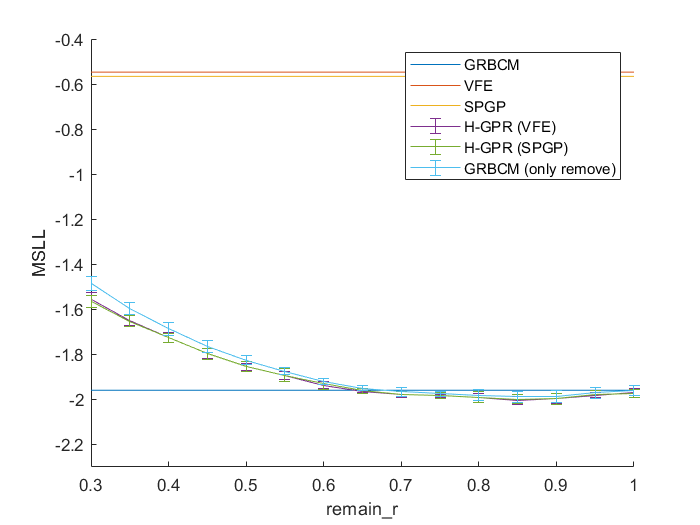

mmsll = mean(aamsll);
mstd = std(aamsll);
mmsll_ro = mean(grbcm_gr_msll(1:kti,:));
mstd_ro = std(grbcm_gr_msll(1:kti,:));
mmsll_sp = mean(grbcm2_spgp_gr_msll(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_msll(1:kti,:));
figure; hold on;
plot([min(grls), max(grls)], [grbcm0_msll,grbcm0_msll]);
plot([min(grls), max(grls)], [vfeMSLL_bl,vfeMSLL_bl]);
plot([min(grls), max(grls)], [spgpMSLL_bl,spgpMSLL_bl]);
errorbar(grls, mmsll, mstd);
errorbar(grls, mmsll_sp, mstd_sp);
errorbar(grls, mmsll_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('MSLL');
ylim([-2.3, -0.4]);

fprintf('Best SMSE (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmse));

Best SMSE (GRBCM+VFE, dcs 150, ecs 150): 0.01211143


fprintf('Best MSLL (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmsll));

Best MSLL (GRBCM+VFE, dcs 150, ecs 150): -2.00461553



fprintf('Best SMSE (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmse_sp));

Best SMSE (GRBCM+SPGP, dcs 150, ecs 150): 0.01191665


fprintf('Best MSLL (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmsll_sp));

Best MSLL (GRBCM+SPGP, dcs 150, ecs 150): -1.99843931


## Experiment II: re-balancing sizes of dcs and ecs

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 50 ;
opts.xvec = xvec;
opts.yvec = yvec;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, []};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

Heuristically rebalancing GRBCM and VFE/SPGP budget based on validating performance.

Obtain results on the validation set.

% default partition
dcs_ecs_r = 0.5;
dcs = round(ttcs*dcs_ecs_r) % size of the communication set

dcs = 150

ecs = ttcs - dcs % size of other experts

ecs = 150


n_per = dcs ; % size of Dc
mn = round(n / ecs); % mn is the number of experts (normal)
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, mn,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = mn+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 

Optimizing hyps in training...
Linesearch      0;  Value 2.554155e+04
Linesearch      1;  Value 1.203778e+04
Linesearch      2;  Value 6.205577e+03
Linesearch      3;  Value 5.647150e+03
Linesearch      4;  Value -2.856793e+03
Linesearch      5;  Value -3.374244e+03
Linesearch      6;  Value -4.417077e+03
Linesearch      7;  Value -4.537702e+03
Linesearch      8;  Value -4.552633e+03
Linesearch      9;  Value -4.555153e+03
Linesearch     10;  Value -4.555334e+03
Linesearch     11;  Value -4.555496e+03
Linesearch     12;  Value -4.555586e+03
Linesearch     13;  Value -4.555596e+03
Linesearch     14;  Value -4.555596e+03
Linesearch     15;  Value -4.555596e+03
Linesearch     16;  Value -4.555596e+03
Linesearch     17;  Value -4.555596e+03
Linesearch     18;  Value -4.555596e+03
Linesearch     19;  Value -4.555596e+03
Linesearch     20;  Value -4.555596e+03
Linesearch     21;  Value -4.555596e+03


opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_val,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_val, ori_yvec_val, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 150): MSE 0.01239359, SMSE 0.01188868, MSLL -1.98765624



g_opts.compute_hyp = 0;

% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
[vfe_hyp, tmp_nlzs] = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value 7.229444e+05
Function evaluation     11;  Value 7.212137e+05
Function evaluation     17;  Value 6.823985e+05
Function evaluation     18;  Value 6.495202e+05
Function evaluation     20;  Value 5.965361e+05
Function evaluation     22;  Value 5.740223e+05
Function evaluation     24;  Value 5.571046e+05
Function evaluation     26;  Value 5.415440e+05
Function evaluation     28;  Value 5.316005e+05
Function evaluation     30;  Value 5.265335e+05
Function evaluation     32;  Value 5.230467e+05
Function evaluation     33;  Value 5.196960e+05
Function evaluation     35;  Value 5.142292e+05
Function evaluation     38;  Value 5.122838e+05
Function evaluation     40;  Value 5.098819e+05
Function evaluation     41;  Value 5.074446e+05
Function evaluation     43;  Value 5.063233e+05
Function evaluation     45;  Value 5.055247e+05
Function evaluation     47;  Value 5.044619e+05
Function evaluation     49;  Value 5.035190e+05
Function evaluation     51;  Value 5.026

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_val);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_val, ori_yvec_val, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE (Dc size 150): MSE 0.34919698, SMSE 0.33497076, MSLL -0.53739727


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_val,models,vfe_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_val, ori_yvec_val, tmu, ts2);
fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);

GRBCM++ (VFE) (Dc size 150): 
MSE 0.01226882, SMSE 0.0118, MSLL -2.0070


sig_temp = 10;
dcs_ecs_r = sigmoid(-MSLL+grbcmMSLL, sig_temp)

dcs_ecs_r = 0.5483

dcs = round(ttcs*dcs_ecs_r)

dcs = 164

ecs = ttcs - dcs

ecs = 136

m = round(n / ecs)

m = 74

n_per = dcs ; % size of Dc
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, m,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = m+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 0;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 
opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 164): MSE 0.01256733, SMSE 0.01196213, MSLL -1.96530623


% grbcm0_smse_rec(ki) = grbcmSMSE; grbcm0_msll_rec(ki) = grbcmMSLL;
g_opts.compute_hyp = 0;

% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
vfe_hyp = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value 6.771657e+05
Function evaluation     16;  Value 5.998275e+05
Function evaluation     19;  Value 5.581266e+05
Function evaluation     22;  Value 5.449867e+05
Function evaluation     24;  Value 5.147507e+05
Function evaluation     26;  Value 5.060681e+05
Function evaluation     28;  Value 4.943599e+05
Function evaluation     30;  Value 4.857384e+05
Function evaluation     32;  Value 4.806604e+05
Function evaluation     34;  Value 4.774503e+05
Function evaluation     37;  Value 4.757455e+05
Function evaluation     39;  Value 4.732163e+05
Function evaluation     41;  Value 4.703673e+05
Function evaluation     44;  Value 4.693126e+05
Function evaluation     46;  Value 4.685113e+05
Function evaluation     48;  Value 4.680056e+05
Function evaluation     49;  Value 4.675208e+05
Function evaluation     51;  Value 4.660696e+05
Function evaluation     53;  Value 4.654481e+05
Function evaluation     55;  Value 4.646997e+05
Function evaluation     57;  Value 4.637

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE baseline', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE baseline (Dc size 164): MSE 0.35266320, SMSE 0.33568030, MSLL -0.56279104


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

sp_opts.induce_size = dcs;
xu = xvec(I_com, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,f] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);

Function evaluation      0;  Value 1.167502e+04
Function evaluation     11;  Value 1.087010e+04
Function evaluation     13;  Value 1.030906e+04
Function evaluation     15;  Value 9.917304e+03
Function evaluation     17;  Value 9.509369e+03
Function evaluation     19;  Value 9.348561e+03
Function evaluation     21;  Value 9.230657e+03
Function evaluation     22;  Value 9.100081e+03
Function evaluation     24;  Value 9.013301e+03
Function evaluation     25;  Value 8.931787e+03
Function evaluation     27;  Value 8.862468e+03
Function evaluation     28;  Value 8.794968e+03
Function evaluation     30;  Value 8.748461e+03
Function evaluation     32;  Value 8.682862e+03
Function evaluation     34;  Value 8.631602e+03
Function evaluation     36;  Value 8.553610e+03
Function evaluation     38;  Value 8.500209e+03
Function evaluation     39;  Value 8.439062e+03
Function evaluation     40;  Value 8.384485e+03
Function evaluation     42;  Value 8.345989e+03
Function evaluation     44;  Value 8.316

xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;

[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE,spgpSMSE,spgpMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG baseline', n_per, spgpMSE,spgpSMSE,spgpMSLL);

SPSG baseline (Dc size 164): MSE 0.38672866, SMSE 0.36810530, MSLL -0.60175932


% spgp0_smse_rec(ki) = spgpSMSE; spgp0_msll_rec(ki) = spgpMSLL;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

[~, minidx] = min(mmsll);
best_msll_gr = grls(minidx)

best_msll_gr = 0.8500


[~, minidx] = min(mmse);
best_smse_gr = grls(minidx)

best_smse_gr = 1

kti = 1;
rb_vfe_msll = zeros(kti, 1);
rb_vfe_smse = zeros(kti, 1);

rb_sp_msll = zeros(kti, 1);
rb_sp_smse = zeros(kti, 1);

for ki=1:kti
    gr = best_msll_gr
    crk = rk;
    crk(I_com) = -1e10;
    [~, crk_idx] = sort(crk, 'descend');
    rn = round(n*gr);
    global_index = zeros(n,1);
    global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance
       
    vfe_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);
    rb_vfe_msll(ki) = MSLL;
    
    sp_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (SPGP)', n_per, MSE,SMSE,MSLL);
    rb_sp_msll(ki) = MSLL;
    
  
    %%%%========================================================================%%
    
    gr = best_smse_gr
    crk = rk;
    crk(I_com) = -1e10;
    [~, crk_idx] = sort(crk, 'descend');
    rn = round(n*gr);
    global_index = zeros(n,1);
    global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance
       
    vfe_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);
    rb_vfe_smse(ki) = SMSE;
    
    sp_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (SPGP)', n_per, MSE,SMSE,MSLL);
    rb_sp_smse(ki) = SMSE;
end

gr = 0.8500

GRBCM++ (VFE) (Dc size 164): 
MSE 0.01350363, SMSE 0.0129, MSLL -1.9789


GRBCM++ (SPGP) (Dc size 164): 
MSE 0.01292443, SMSE 0.0123, MSLL -1.9922


gr = 1

GRBCM++ (VFE) (Dc size 164): 
MSE 0.01291452, SMSE 0.0123, MSLL -1.9694


GRBCM++ (SPGP) (Dc size 164): 
MSE 0.01234696, SMSE 0.0118, MSLL -1.9771


fprintf('Best SMSE (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, mean(rb_vfe_smse));

Best SMSE (GRBCM+VFE, dcs 164, ecs 136): 0.01229260


fprintf('Best MSLL (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, mean(rb_vfe_msll));

Best MSLL (GRBCM+VFE, dcs 164, ecs 136): -1.97891661



fprintf('Best SMSE (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, mean(rb_sp_smse));

Best SMSE (GRBCM+SPGP, dcs 164, ecs 136): 0.01175238


fprintf('Best MSLL (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, mean(rb_sp_msll));

Best MSLL (GRBCM+SPGP, dcs 164, ecs 136): -1.99219990
